% preliminary stuff


data = readmatrix("2019-04.csv")

data = 1.0e+07 *

       NaN         0         0    0.0000    0.0000    0.0000         0         0    0.0000    0.0000    0.0000    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0         0         0         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000         0         0         0         0         0    0.0000         0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
       NaN    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000 

S_PDivYield = data(4:189,248)

S_PDivYield =     3.1012
    3.0720
    3.1572
    3.3850
    3.4726
    3.5002
    3.5259
    3.1370
    2.9402
    2.9234


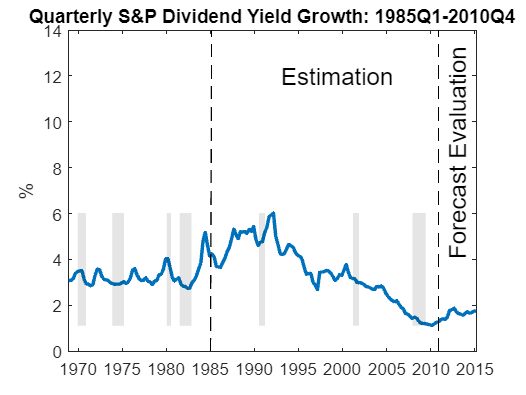


save esametimetrimestrale.mat

load('esametimetrimestrale.mat')

t = datetime(1968,12,01):calquarters(1):datetime(2015,03,01); t =t';

plot(t,S_PDivYield,'linewidth',2); axis tight; recessionplot;
title('Quarterly S&P Dividend Yield Growth: 1985Q1-2010Q4'); ylabel('%'); hold on;
plot([datetime(1985,01,01) datetime(1985,03,01)],[0 14],'--k'); hold on
plot([datetime(2010,12,01) datetime(2010,12,01)],[0 14],'--k'); hold off
text([datetime(1993,1,01)],12,'Estimation','Fontsize',14);
text([datetime(2013,1,01)],4,'Forecast Evaluation','Fontsize',14,'Rotation',90);

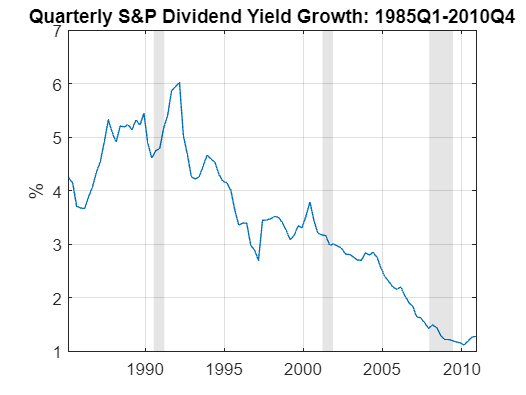


t_est = (datetime(1985,3,01):calquarters(1):datetime(2010,12,01))';
y = S_PDivYield(ismember(t,t_est));
plot(t_est,y); recessionplot;
title('Quarterly S&P Dividend Yield Growth: 1985Q1-2010Q4'); ylabel('%'); grid on

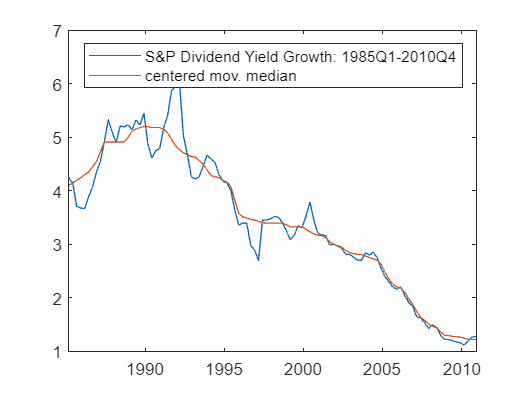

plot(t_est,[y movmedian(y,4*5)]);
legend('S&P Dividend Yield Growth: 1985Q1-2010Q4','centered mov. median')

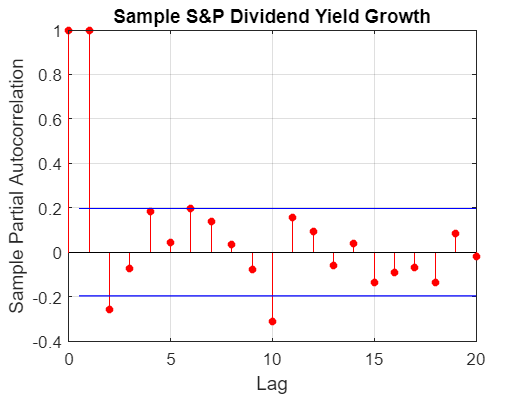


parcorr(y,4*5); title('Sample S&P Dividend Yield Growth')

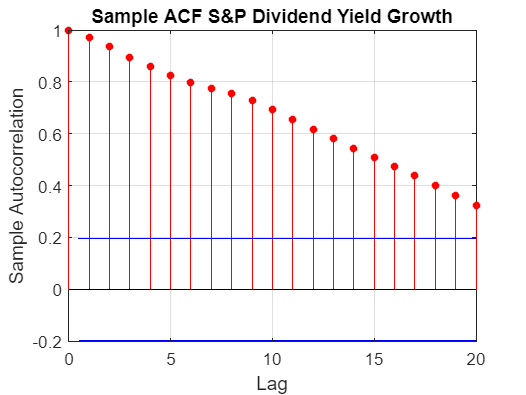


autocorr(y,4*5); title('Sample ACF S&P Dividend Yield Growth')



t_est2 = (datetime(1985,9,01):calquarters(1):datetime(2010,12,01))';
y2 = diff(y)

y2 =    -0.0995
   -0.4352
   -0.0291
   -0.0152
    0.2211
    0.1887
    0.2740
    0.1980
    0.3673
    0.4136


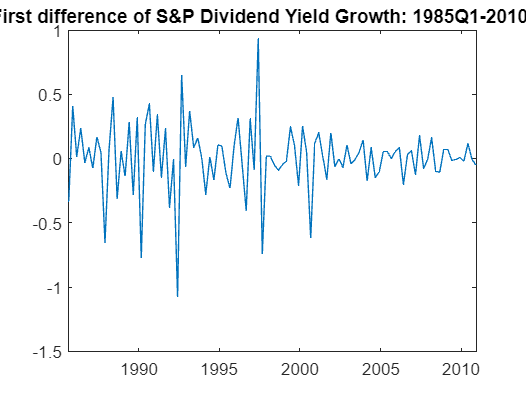


plot(t_est2,[diff(y2)]); title('First difference of S&P Dividend Yield Growth: 1985Q1-2010Q4')